syms T
g = 9.81;
% Data voor 180

% Hefboomafstand in cm
d180 = 12.2 ;

% Massa in g
mass180 = [280, 277, 281, 269, 284];


% Gewicht op de weegschaal in N
F180 = (mass180/1000)*g;

% Moment dat motor levert in Nm
M180 = F180*(d180/100)

M180 =     0.3351    0.3315    0.3363    0.3219    0.3399



% Getrokken stroom in mA
I0180 = [10 12 9 8 13]*0.001;
Istall180 = [720, 770, 740, 750, 750]*0.001

Istall180 =     0.7200    0.7700    0.7400    0.7500    0.7500




% Data voor 360

% Hefboomafstand in cm
d360 = 13.3; 

% Massa in g
mass360 = [111, 112, 140, 123, 120];

% Gewicht op de weegschaal in N
F360 = (mass360/1000)*g;

% Moment dat motor levert in Nm
M360 = F360*(d360/100)

M360 =     0.1448    0.1461    0.1827    0.1605    0.1566



% Getrokken stroom in A
I0360 = [170 168 175 177 166]*0.001;
Istall360 = [570, 570, 560, 550, 540]*0.001

Istall360 =     0.5700    0.5700    0.5600    0.5500    0.5400


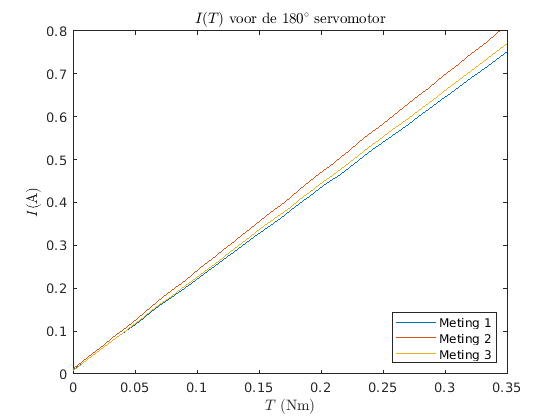


% Opstellen van de grafiek van I(T) voor de 180 servo
I1_180(T) = (Istall180(1) - I0180(1))/M180(1)*T + I0180(1);
I2_180(T) = (Istall180(2) - I0180(2))/M180(2)*T + I0180(2);
I3_180(T) = (Istall180(3) - I0180(3))/M180(3)*T + I0180(3);
fplot(I1_180(T), [0, 0.35])
hold on
fplot(I2_180(T), [0, 0.35])
hold on 
fplot(I3_180(T), [0, 0.35])

xlabel('$T$ (Nm)', 'Interpreter','latex');
ylabel('$I$(A)','Interpreter','latex');
legend('Meting 1', 'Meting 2', 'Meting 3', Location='southeast');
xlim([0, 0.35]);
ylim([0 0.8]);
title('$I(T)$ voor de $180^\circ$ servomotor', 'Interpreter', 'latex');
hold off

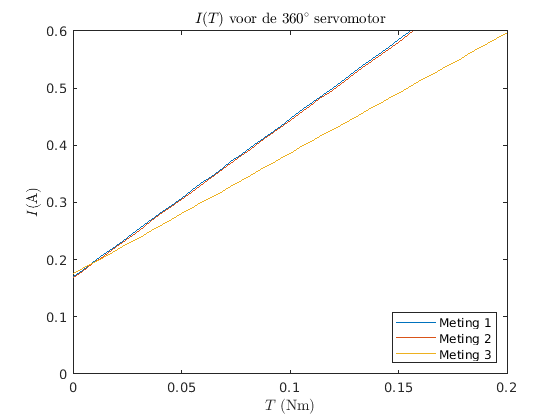


% Opstellen van de grafiek van I(T) voor de 360 servo
I1_360(T) = (Istall360(1) - I0360(1))/M360(1)*T + I0360(1);
I2_360(T) = (Istall360(2) - I0360(2))/M360(2)*T + I0360(2);
I3_360(T) = (Istall360(3) - I0360(3))/M360(3)*T + I0360(3);

fplot(I1_360(T), [0, 0.2])
hold on
fplot(I2_360(T), [0, 0.2])
hold on 
fplot(I3_360(T), [0, 0.2])

xlabel('$T$ (Nm)', 'Interpreter','latex');
ylabel('$I$(A)','Interpreter','latex');
legend('Meting 1', 'Meting 2', 'Meting 3', Location='southeast');
xlim([0, 0.2]);
ylim([0, 0.6]);
title('$I(T)$ voor de $360^\circ$ servomotor', 'Interpreter', 'latex');
hold off